## Parametric Sweep for HTSAAM Machine

### Main Machine Parameters

%Clear all
clc;
clear all

%Optimization Outputs
machine.Npole = 240;
stator.current_density = 6 %solution(2);     % Current Density (A/mm^2)

stator = struct with fields:
    current_density: 6


Parameter Sweep adjustment

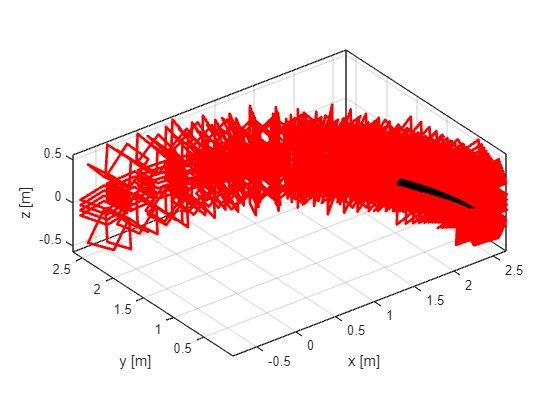

sweep.min = 40;
sweep.max = 200;
sweep.number = 40;

%Create output matrix;
output = zeros (sweep.number,4);

for i=1:sweep.number

    machine.Npole = sweep.min + (i-1)*((sweep.max - sweep.min)/sweep.number);
    main;

    output (i,1) = machine.Npole;
    output (i,2) = machine.P_output/1e6;  %MW
    output (i,3) = machine.efficiency;
    output (i,4) = HTS.length_total/1000; %km


end

## Results

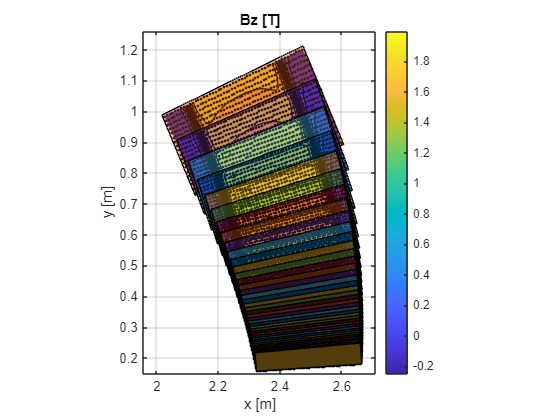


tiledlayout("vertical")  %Subplot

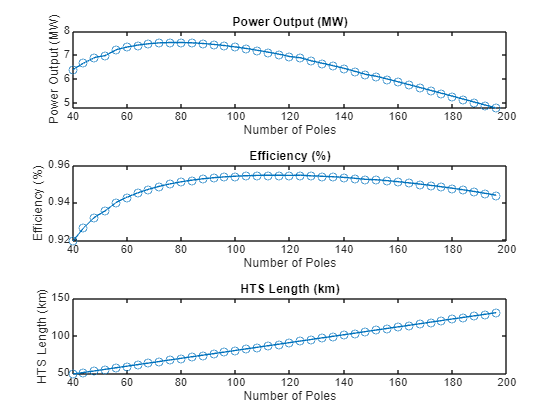

nexttile
plot(output(:,1), output(:,2),'-o')
title("Power Output (MW)")
xlabel('Number of Poles') 
ylabel('Power Output (MW)') 

nexttile
plot(output(:,1), output(:,3),'-o')
title("Efficiency (%)")
xlabel('Number of Poles') 
ylabel('Efficiency (%)') 

nexttile
plot(output(:,1), output(:,4),'-o')
title("HTS Length (km)")
xlabel('Number of Poles') 
ylabel('HTS Length (km)') 